# Получаем mean and std для гауссов

z - звуковой сигнал

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

data - Каждый столбец - звук отдельной **ноты**

NOTES = 88;
data = reshape(z,4*Fs,[]);
NFFT = 1024;

t_one = 2;                  % Одна нота длится 2 секунды
dt = 1/Fs;                  % Время между отчетами
t_min = NFFT*dt;              % Время вырезки
N_row = floor(t_one/t_min); % Количество вырезок за 2 секунды
N = N_row;

mean_pdf = zeros([NFFT/2, NOTES]);
std_pdf = zeros([NFFT/2, NOTES]);

for num_notes = 1 : NOTES
    notes = reshape(data(1:NFFT*N,num_notes),NFFT,N);
    notes = abs(fft(notes));
    mean_pdf(:,num_notes) = mean(notes(1:NFFT/2,:),2);
    std_pdf(:,num_notes) = std(notes(1:NFFT/2,:),1,2);   % Maybe we must set 0 for secod parameter
    
end

Вывожу результаты

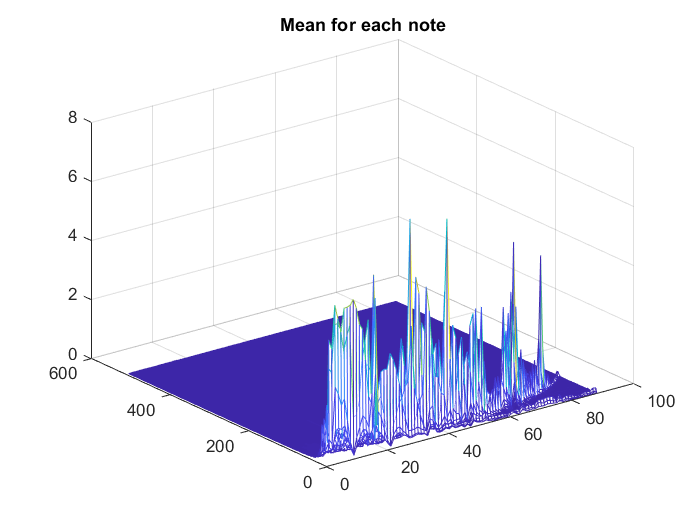

figure 
mesh(mean_pdf)
title('Mean for each note')

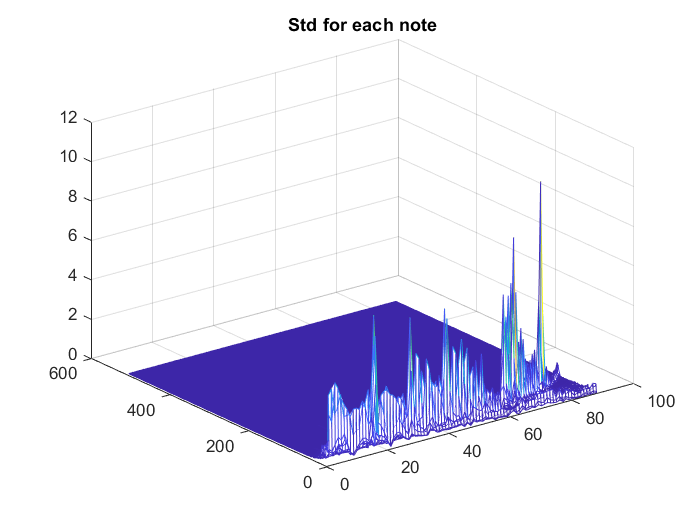


figure 
mesh(std_pdf)
title('Std for each note')

# Обучение по временному сигналу байесовского классификатора

- Each row of X contains features, that represents class filled in corresponding row in Y

- size (X) = N_row*NOTES x NFFT

- size (Y) = N_row*NOTES x 1

Заполняю X and Y

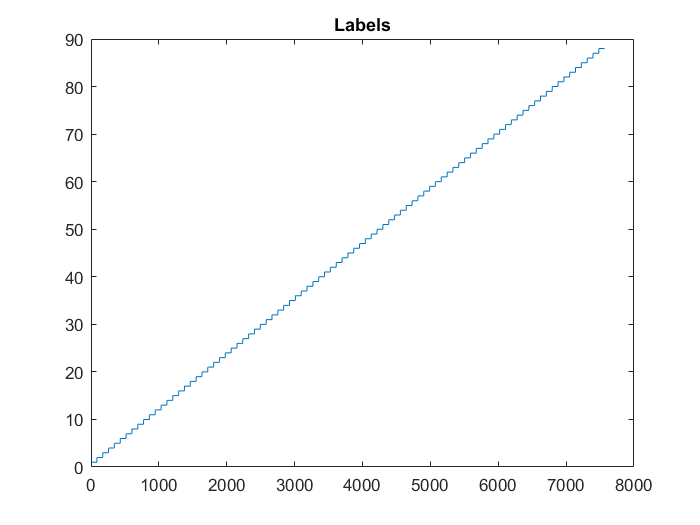

Y = zeros(N_row*NOTES, 1);
X = zeros([N_row*NOTES, NFFT]);

N_one = 2 * Fs;             % Кол-во отчетов на 1 ноту
N_shift = 2*N_one;          % Сдвиг по отчетам на ноту

data = data(1:N*NFFT, :);   % Без нулей

for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),1024,[])';
    
    X(N1:N2, :) = notes;
    Y(N1:N2) = k;
    
end
save('data.mat', 'data', 'X', 'Y')

figure
plot(Y)
title("Labels")

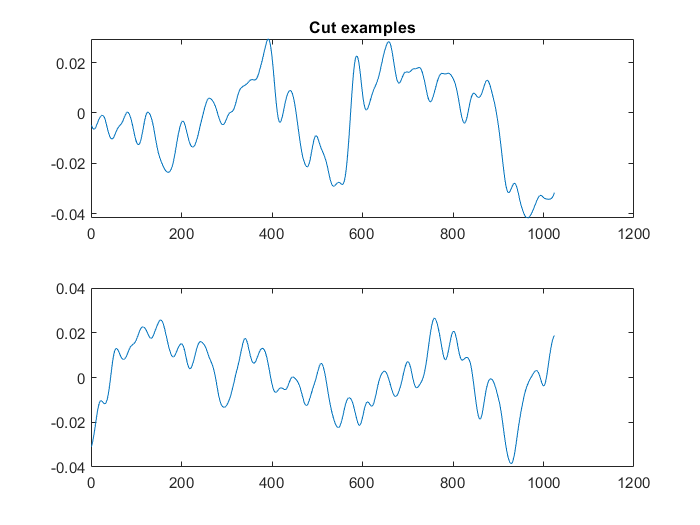


figure
subplot(2,1,1)
plot(X(200,:))
title("Cut examples")
subplot(2,1,2)
plot(X(201,:))

Начинаю обучение

% Mdl_time = fitcnb(X,Y)
% Mdl_time.ClassNames
% 
% CVMdl_time = fitcnb(X,Y,'CrossVal','on')
% CVMdl_time.Trained{1}
% genError = kfoldLoss(CVMdl_time)
% 
% X_spec = abs(fft(X'))';
% 
% Mdl_freq = fitcnb(X_spec,Y)
% Mdl_freq.ClassNames
% 
% CVMdl_freq = fitcnb(X_spec,Y,'CrossVal','on')
% CVMdl_freq.Trained{1}
% genError = kfoldLoss(CVMdl_freq)
% 
% % save('BaiesTrainedFreq.mat', 'CVMdl_freq', 'Mdl_freq')
% % save('BaiesTrainedTime.mat', 'CVMdl_time', 'Mdl_time')
save('data.mat', 'data', 'X', 'Y')

# Обучение и Проверка байесовского классификатора

clear all
close all

% load("BaiesTrainedTime.mat");
% load("BaiesTrainedFreq.mat");
load("data.mat");

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

Обучение и Тест

Mdl = fitcnb(XTrain,YTrain);
label = predict(Mdl,XTest);
table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2270×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        1              29      
        1              16      
        1              64      
        1               6      
        1              76      
        1               4      
        1              21      
        1               9      
        1              41      
        1              17      
        1              17      
        1              21      
        1              18      
        1              46      
        1              21      
        1              36      


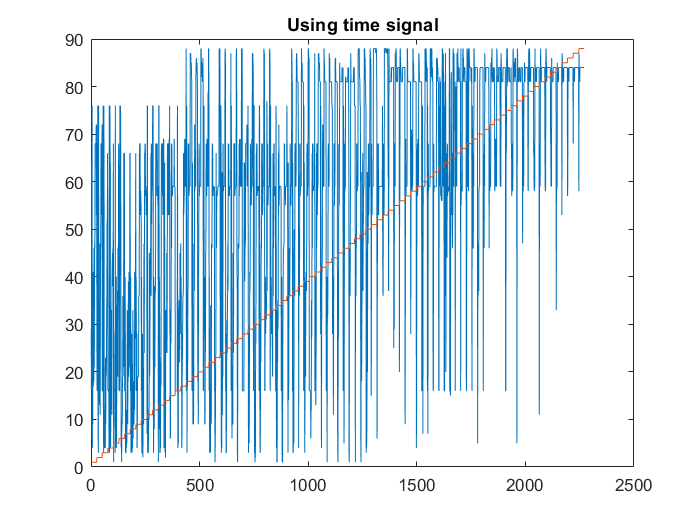


figure
plot(label)
hold on
plot(YTest)
title('Using time signal')

Обучение и Тест по спектрам

for i = 1:length(XTest)
    XTest(i, :) = abs(fft(XTest(i, :)));
end
for i = 1:length(XTrain)
    XTrain(i, :) = abs(fft(XTrain(i, :)));
end

Mdl_freq = fitcnb(XTrain,YTrain);
label = predict(Mdl_freq,XTest);
table(YTest,label,'VariableNames',...
    {'TrueLabel','PredictedLabel'})

ans = 2270×2 table
    TrueLabel    PredictedLabel
    _________    ______________

        1               8      
        1               7      
        1              16      
        1               3      
        1               8      
        1               9      
        1               7      
        1               7      
        1               9      
        1               8      
        1               8      
        1               8      
        1               9      
        1               9      
        1               9      
        1               9      


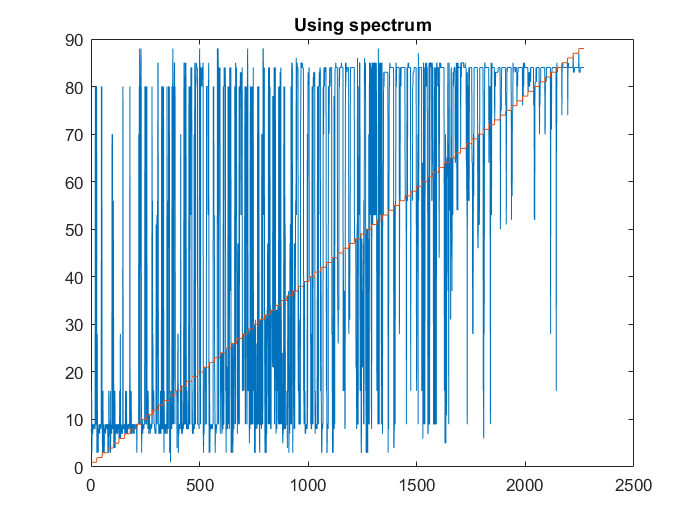


figure
plot(label)
hold on
plot(YTest)
title('Using spectrum')

Пример как брать fft в матрице по строкам (транспонируем и берем по столбцам)

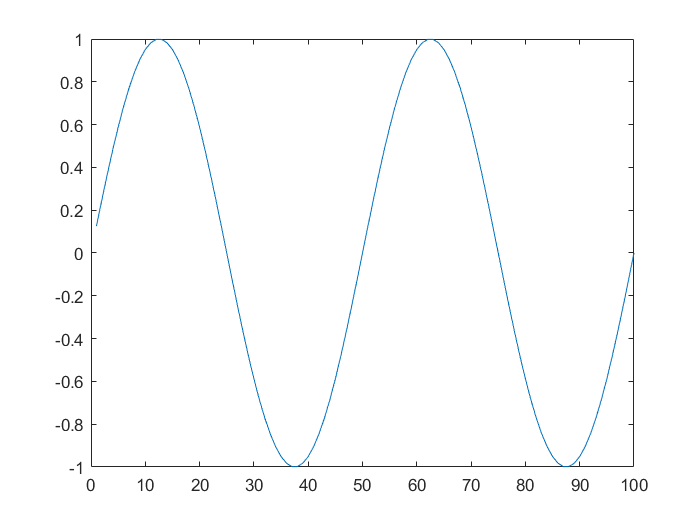

t = 1:100;
w0 = 2*pi/50;
x1 = sin(t*w0);
x2 = 2*sin(3*t*w0);

figure
plot(x1)

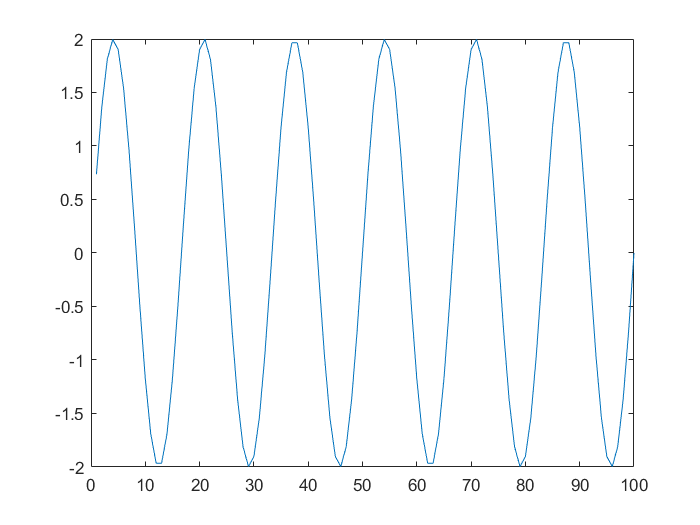


figure
plot(x2)

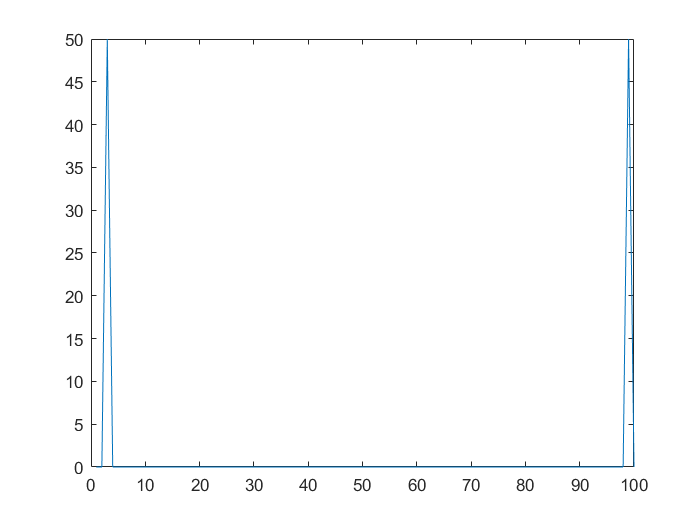


x = [x1; x2];
x_spec = abs(fft(x'));

figure
plot(x_spec(:,1))

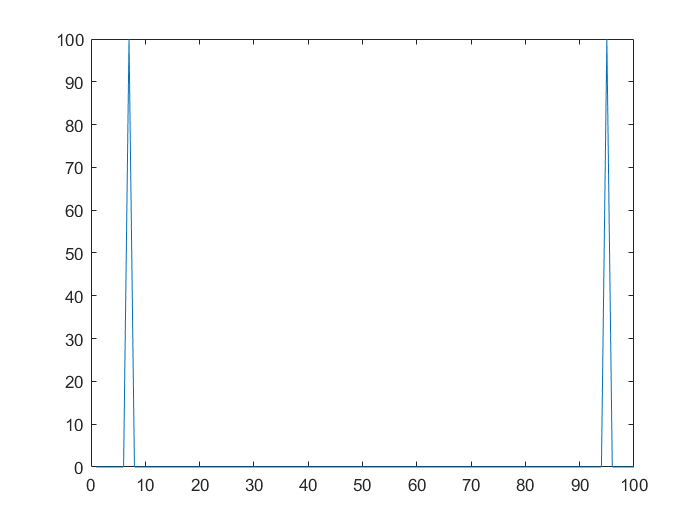


figure
plot(x_spec(:,2))

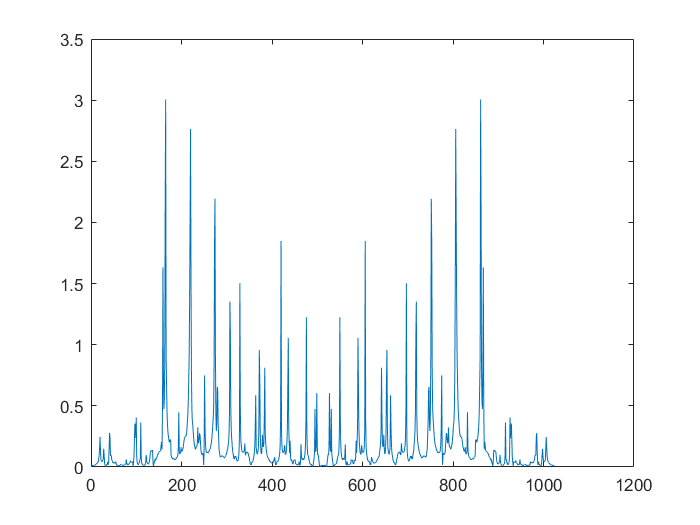


X_spec = abs(fft(X'));

figure
plot(X_spec(:,1))

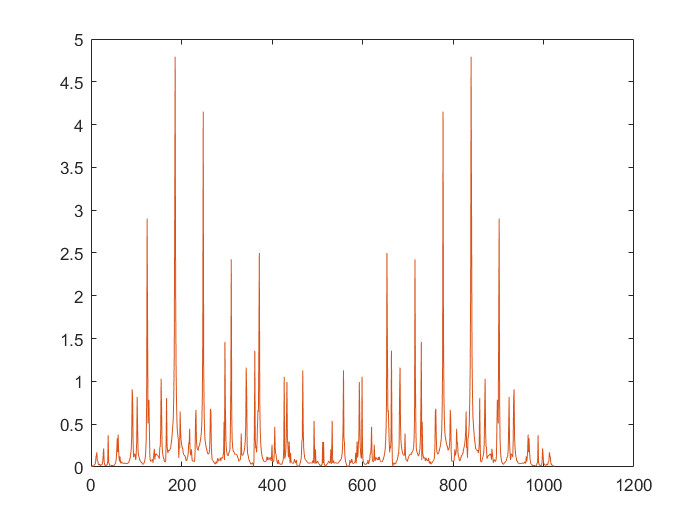


figure
XX1 = X_spec(:,200)';
X1 = abs(fft(X(200,:)));
plot(X1)
hold on
plot(XX1)